## 一阶导数零点

### 极值点

#### roots[系数,...,系数n]

例1：

% Step 1: 求导
syms x
diff(x^3-2*x+1)

$$ans = 3\,x^{2}-2$$

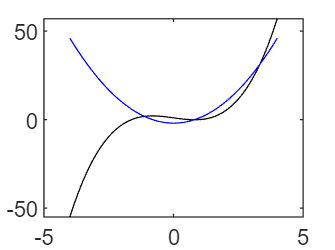


% Step 2: 定范围+画图
x=-4:0.1:4;
y1=x.^3-2*x+1;
y2=3*x.^2-2;
plot(x, y1, 'k-', x, y2, 'b-')


% Step 3: 求一阶导的根
c = roots([3,0,-2])

c =     0.8165
   -0.8165


## 最值

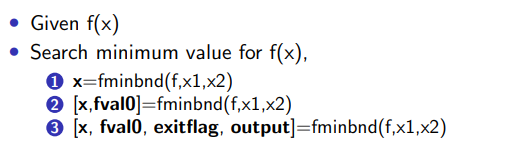

### 求极小值

#### [xmin,ymin]=fminbnd(f, x1, x2)

f在[x1,x2]范围内，在x=xmin处取极小，极小值为ymin

f为字符串型

例1：

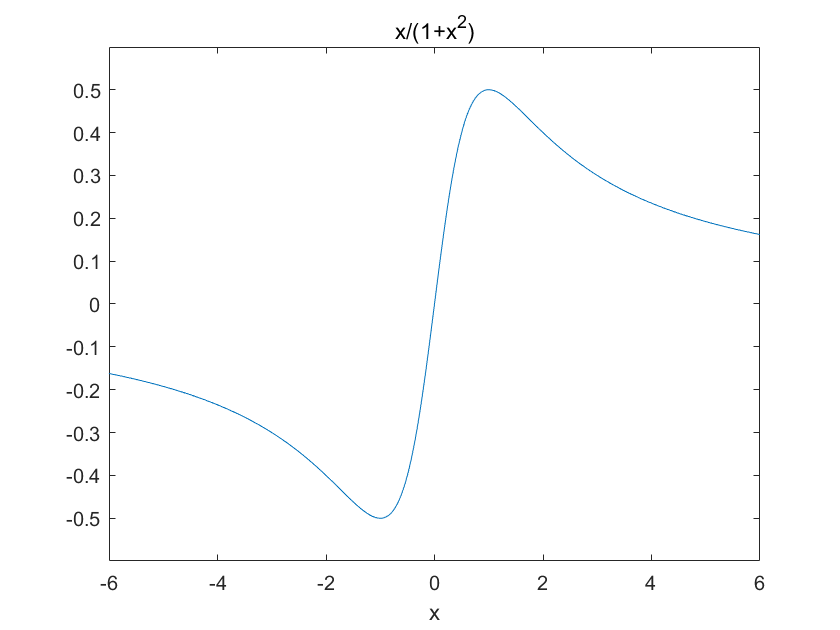

% Step 1: 画出函数
ezplot('x/(1+x^2)', [-6,6])


clear;syms x
f='x/(1+x^2)';
[xmin,ymin]=fminbnd(f,-10,10)

xmin = -1.0000

ymin = -0.5000

### 求极大值

求f的极大值 <=> 求-f的极小值

注意最后得到的y不是最终结果

-y才是

clear;syms x
f='-x/(1+x^2)';
[xmax,ymax]=fminbnd(f,-10,10)

xmax = 1.0000

ymax = -0.5000

例2：

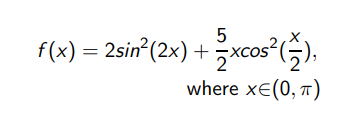

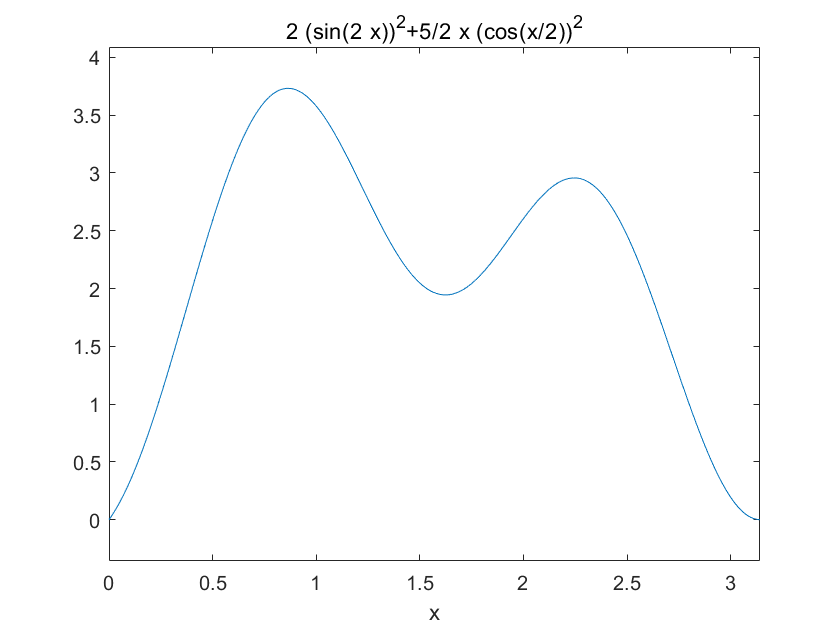

% 画原图
ezplot('2*(sin(2*x))^2+5/2*x*(cos(x/2))^2', [0, pi])


% 求最大值
clear;
f='2*(sin(2*x))^2+5/2*x*(cos(x/2))^2';
f1='-2*(sin(2*x))^2-5/2*x*(cos(x/2))^2';
[xmin,ymin]=fminbnd(f,0,pi)%最小

xmin = 1.6239

ymin = 1.9446

[xmax1,ymax1]=fminbnd(f1,0,1)%0~1里最大

xmax1 = 0.8642

ymax1 = -3.7323

[xmax2,ymax2]=fminbnd(f1,1.5,pi)%1.5~pi里最大

xmax2 = 2.2449

ymax2 = -2.9571


% 当范围内有多个极值点时，该函数只会显示最大/小的那一个极值
clear;
f1='-2*(sin(2*x))^2-5/2*x*(cos(x/2))^2';
[xmax,ymax]=fminbnd(f1,0,pi)

xmax = 0.8642

ymax = -3.7323

### 证明不等式

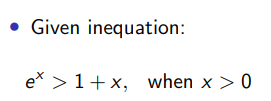

<=> f=e^x-x-1在[0,inf]内单调递增

<=> f=e^x-x-1在[0,inf]的极小值大于0.可证得

####  fzero(f, X0) 

fzero(f, x0)表示求x0附近零点

fzero(f, [a, b])表示求[a, b]区间内零点

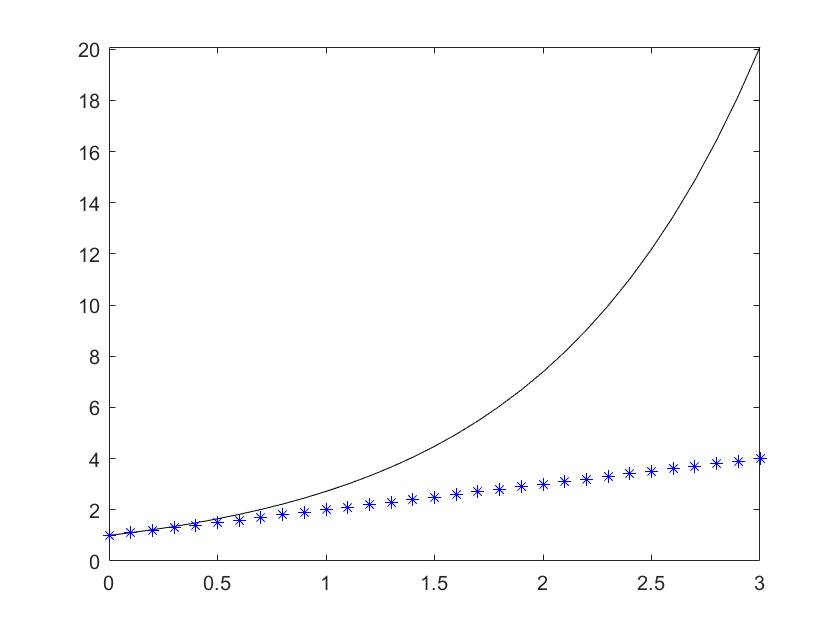

% 画原图
clear;
x=0:0.1:3;
f1=exp(x);
f2=1+x;
plot(x,f1,'k-',x,f2,'b*')


% 求f'的极小值
clear;syms x;
f=exp(x)-x-1

$$f = {\mathrm{e}}^{x}-x-1$$

df=diff(f,x)

$$df = {\mathrm{e}}^{x}-1$$

c=fzero('exp(x)-x-1', 0)

c = 0

f1 = 'exp(x)-x-1'

x1 = 5.2628e-05

y1 = 1.3849e-09

ans =     97   110   115
